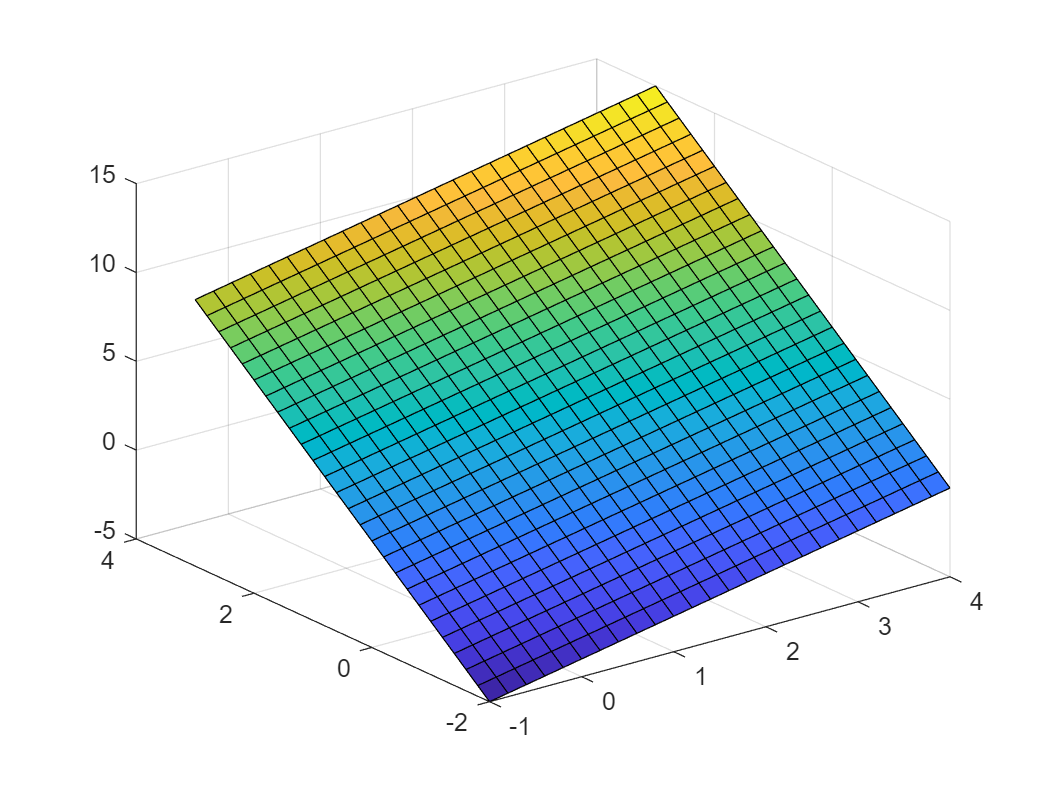

clear
w=[3;1];
x1=[-1:.2:4];
x2=[-2:.2:3];
x3=[x1;x2];
b=1;
for i=1:length(x1)
for k=1:length(x2)
x(:,b)=[x3(1,i);x3(2,k)];
y(i,k)=w'*x(:,b);
b=b+1;
end
end
surf(x1,x2,y);

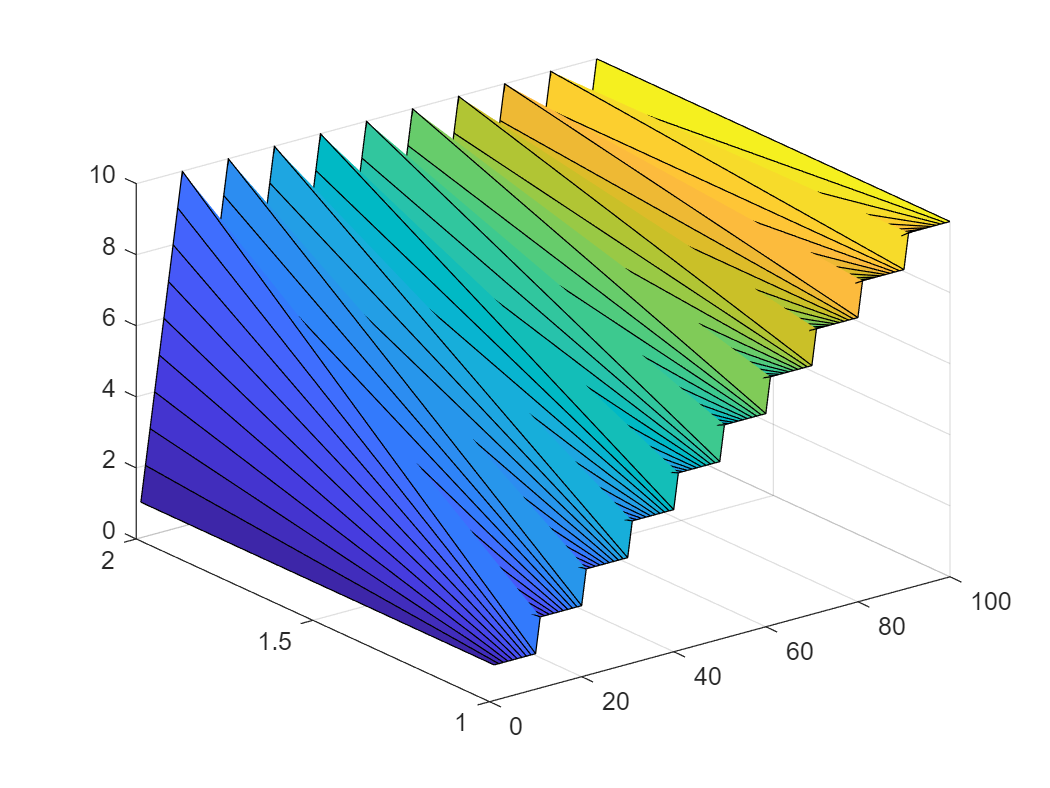


clear
w=[3;1];
x1=[1:10];
x2=[1:10];
x3=[x1;x2];
b=1;
for i=1:length(x1)
for k=1:length(x2)
x(:,b)=[x3(1,i);x3(2,k)];
b=b+1;
end
end

y=w'*x;

surf(x,y);

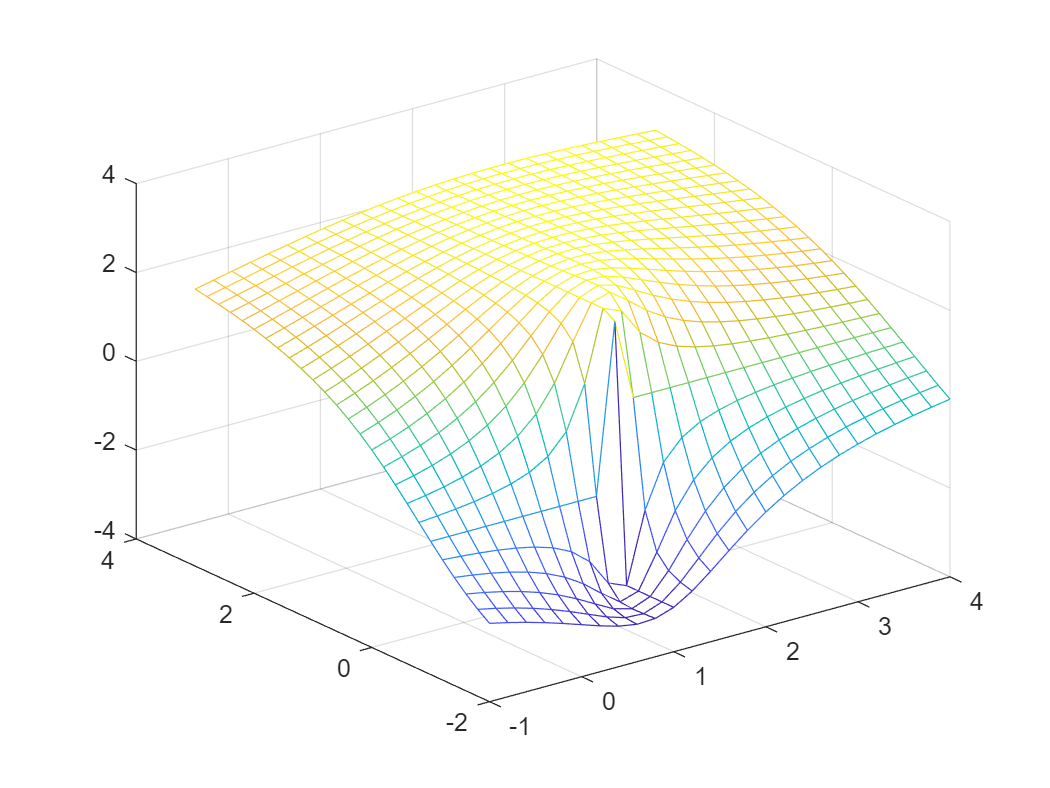

clear
w=[3;1];
x1=[-1:.2:4];
x2=[-2:.2:3];
x3=[x1;x2];
b=1;
for i=1:length(x1)
for k=1:length(x2)
x(:,b)=[x3(1,i);x3(2,k)];
y(i,k)=w'*normc(x(:,b));
b=b+1;
end
end

mesh(x1,x2,y);

clear

w=[4,2,1;0.01,-1,3.5;0.01,2,0.01;-1,2.5,-2;-1.5,2,1.5];
fox=[4;-1;-1;-0.9;-1];
salmon=[-1;4;-1;-2;1];
chicken =[2;-1;0.01;3;3];
cat=[4;0;0;-0.5;-2];
x=[ fox, salmon, chicken, cat];
y=w'*x;
disp('x');

x


disp(x);

    4.0000   -1.0000    2.0000    4.0000
   -1.0000    4.0000   -1.0000         0
   -1.0000   -1.0000    0.0100         0
   -0.9000   -2.0000    3.0000   -0.5000
   -1.0000    1.0000    3.0000   -2.0000



disp('y');

y


disp(y);

   18.3800   -3.4700    0.4901   19.5000
    2.7500  -11.0000   18.5200    2.7500
    0.7900   18.4900   -2.9999    2.0000





y=w'*normc(x);
disp('y when normc(x)');

y when normc(x)


disp(y);

    4.1296   -0.7235    0.1022    4.3333
    0.6179   -2.2937    3.8617    0.6111
    0.1775    3.8554   -0.6255    0.4444




y=normc(w)'*x;
disp('y when normc(w)');

y when normc(w)


disp(y);

    4.1892   -0.7909    0.1117    4.4444
    0.6268   -2.5071    4.2211    0.6268
    0.1789    4.1871   -0.6793    0.4529





y=normc(w)'*normc(x);
disp('y when normc(x) and normc(w)');

y when normc(x) and normc(w)


disp(y);

    0.9412   -0.1649    0.0233    0.9877
    0.1408   -0.5228    0.8802    0.1393
    0.0402    0.8731   -0.1417    0.1006



clear
w=[3;1];
x1=-1:.2:4;
x2=-2:.2:3;
x3=[x1;x2];
b=1;
xu=[];
for i=1:length(x1)
for k=1:length(x2)
x(:,b)=[x3(1,i);x3(2,k)];
xu=[xu x(:,b)];
b=b+1;
end
end
t=w'*xu;
disp(size(t));

     1   676




w=[3;1];
x1=-1:.2:4;
x2=-2:.2:3;
x3=[x1;x2];
b=1;
xu=[];
for i=1:length(x1)
for k=1:length(x2)
x(:,b)=[x3(1,i);x3(2,k)];
y(i,k)=sim(results,x(:,b));
b=b+1;
end
end

'model' parameter must be a character vector

t=w'*xu;
disp(size(t));

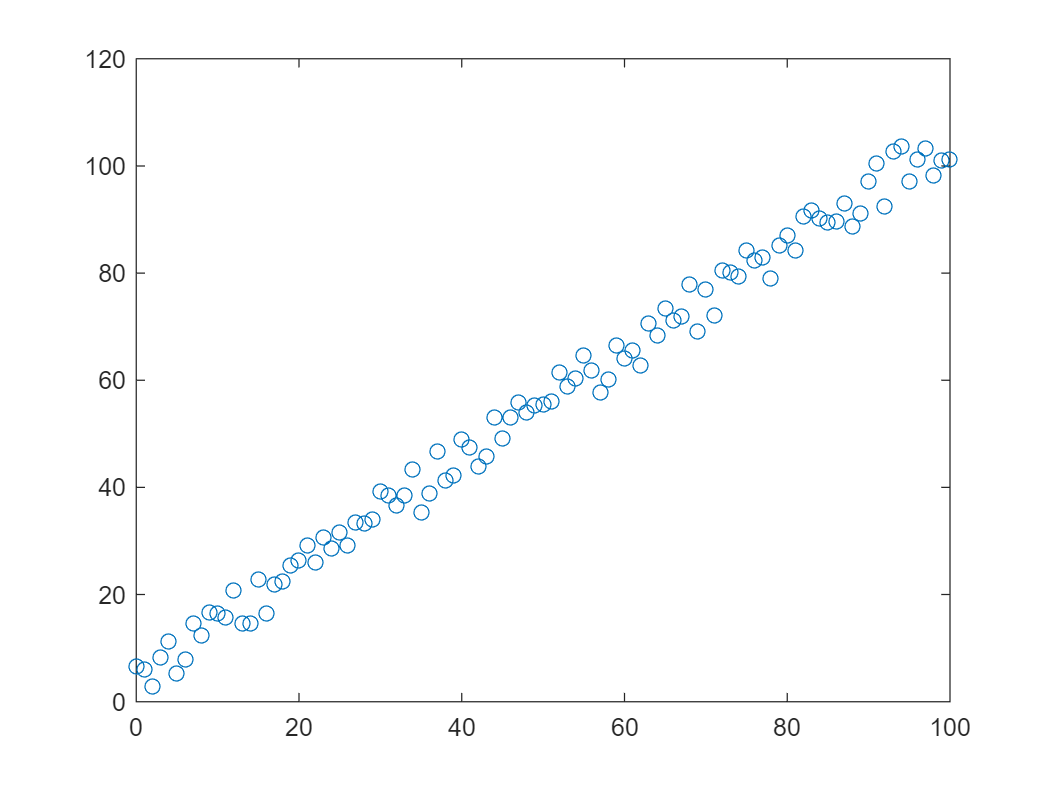

x=0:100;
z=10*rand(1,101);
y=x+z;

plot(x,y,'o');